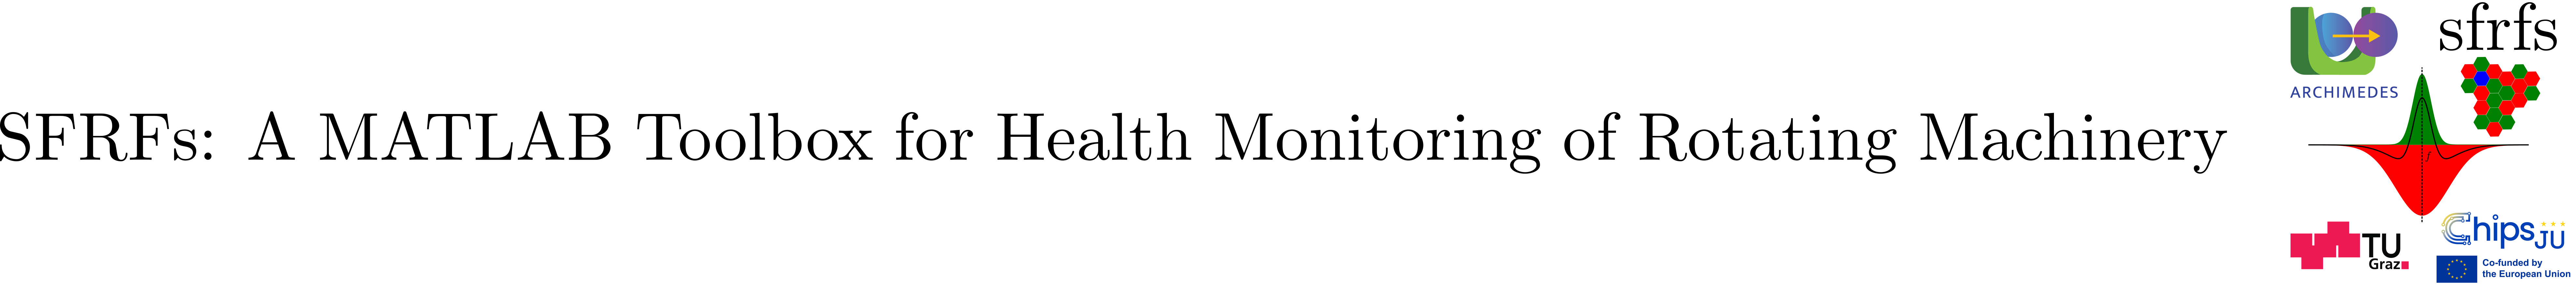

# RFGFViewer

## Summary

`RFGFViewer` is an embeddable visualization component for inspecting receptive field gain functions (RFGFs) generated by a `ReceptiveFieldGainFunctions `instance. It renders the center mask, surround mask, and their contrast over the frequency axis, and supports plotting into a provided axes/uiaxes or creating its own figure if none is supplied.

## Description

`RFGFViewer` provides a lightweight rendering layer on top of the `ReceptiveFieldGainFunctions` table representation. The viewer resolves a single row from `rfgfs.gainFunctionsTable` either directly by row index, or by combining a `faultType` with an operating-condition selection object. From the resolved row, it extracts the stored center and surround masks, retrieves the fault-specific inhibition factor `k` from the associated `frequencyBands `object, and renders the selected gain profiles over the shared frequency domain. 

Behavior:

- The viewer plots *Center*, *Surround*, and a *contrast profile* defined as $c- ks$, where $k$ is the fault-type specific inhibition factorr esolved via the viewer’s associated `frequencyBands` object.

- The *Surround* curve is displayed as `-Surround` for visual alignmentwith the contrast convention; this sign flip is only for plotting.

- The viewer operates at the gain-function level and does not require signal data; it visualizes the parameterized center-surround masks over the frequency domain.

- The legend label for the contrast curve includes the resolved inhibition factor k for transparency.

### Properties

Notes:

- `showCenter`, `showSurround`, `showContrast` are currently toggled by setting the properties on the viewer instance.

- `frequencyLimits` can be set as a viewer property, or overridden per call via`render(frequencyLimits=...)`.

### Constructor

#### Syntax

- `RFGFViewer(Name=Value, ...)`

It stores the `ReceptiveFieldGainFunctions` instance and configures basic rendering preferences.

#### Parameters

### Methods

#### `render` selection rules

Exactly one selection mechanism must be used:

- **Row selection**: `render(row=...)`

- **Semantic selection**: `render(faultType=..., selection=...)`This requires an `OperatingConditionSelection` object and the toolbox’srow-resolution helper (`FaultConditionSelector.selectRow`).

#### `render` parameters

### See also

[RunToFailureSFRFsViewer](matlab:open('./RunToFailureSFRFsViewer.mlx')), [RunToFailureRFGFsFilteredSpectraViewer](matlab:open('./RunToFailureRFGFsFilteredSpectraViewer.mlx')), [CenterSurroundCompute](matlab:open('./CenterSurroundCompute.mlx')), [ReceptiveFieldResponseFunctions](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [ContrastMappings](matlab:open('./ContrastMappings.mlx'))

## Example

Recommended usage is to construct `rfgfs` first (via `ReceptiveFieldGainFunctions`) and then render a selected entry. The simplest example uses direct row selection (no dependency on `OperatingConditionSelection`).

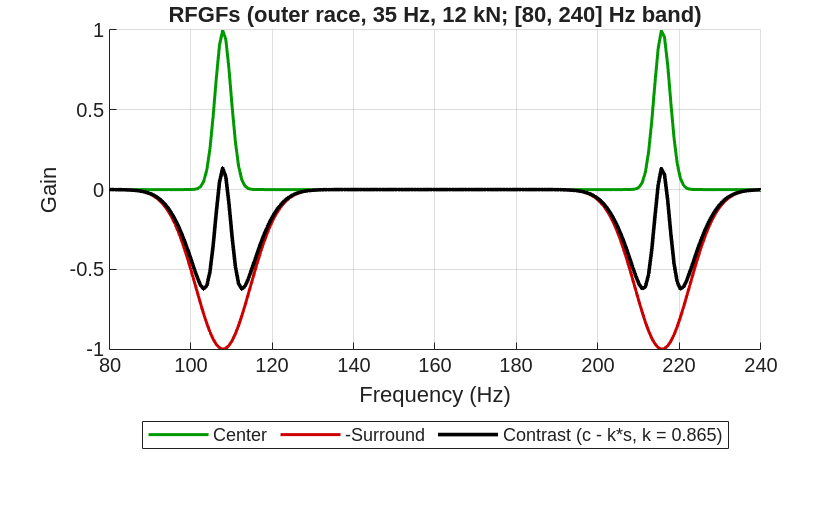

%% RFGFViewer: self-contained example (rolling bearings, XJTU-SY settings)

% Snapshot descriptor (XJTU-SY see Wang et al.[2])
sp = ParametersSnapshot( ...
    samplingFrequency = 25600, ...
    duration = 1.28, ...
    stride = 60);

% Bearing geometry
bp = ParametersRollingBearings( ...
    numRollingElements = 8, ...
    ballDiameter = 7.92, ...
    pitchDiameter = 34.55, ...
    contactAngle = 0);

% Operating conditions (XJTU-SY)
speedHz = [35; 37.5; 40];
loadN   = [12; 11; 10];
oc = OperatingConditions(speedHz, loadN);

% Shared SFRFs mask parameterization (Gaussian)
sharedParams = SFRFsParameters.buildSFRFsParameters( ...
    order = 0, ...
    numSidebands = 2, ...
    numHarmonics = 10, ...
    centerMask = GaussianMaskParameters( ...
        bandwidth = 4, ...
        sigmaRule = 1.0253), ...
    surroundMask = GaussianMaskParameters( ...
        bandwidth = 12, ...
        sigmaRule = 0.8905), ...
    inhibitionFactor = 0.8647);

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

% Build frequency bands and gain functions
bfb = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sfrfsParams, ...
    operatingConditions = oc);
bfb.computeBands();

rfgfs = ReceptiveFieldGainFunctions(bfb);

f = sp.getFrequencyDomain();
rfgfs.computeGainFunctions(f);

% Create a viewer (embeddable)
viewer = viz.RFGFViewer(rfgfs = rfgfs);
viewer.showLegend = true;

% Semantic row selection (fault type + operating condition)
sel = OperatingConditionSelection(speed = 35, load = 12);
ft  = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;

ax = viewer.render( ...
    faultType = ft, ...
    selection = sel, ...
    frequencyLimits = [80 240], ...
    titleText = "RFGFs (outer race, 35 Hz, 12 kN; [80, 240] Hz band)");

grid(ax, "on");
xlabel(ax, "Frequency (Hz)");
ylabel(ax, "Gain");

## API documentation

### MATLAB help

help viz.RFGFViewer

 RFGFViewer  Embeddable viewer for receptive field gain functions (RFGFs).
 
    viewer = RFGFViewer(Name=Value, ...)
    ax = viewer.render(Name=Value, ...)
 
  Constructor configures rendering preferences.
  render() is parameterized by selection:
    - row
    - faultType + selection

    Documentation for viz.RFGFViewer



## Source code

The source of the class can be found in [RFGFViewer](matlab:open('../../+viz/RFGFViewer.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).